# EQUACIONS DIFERENCIALS (I)

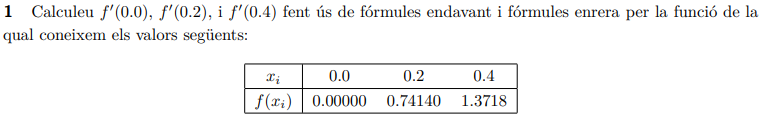

clearvars;
format short g;
x = [0 0.2 0.4]; y = [0 0.74140 1.3718];
yp(1) = (y(2)-y(1))/0.2;    % f'(0) endavant
yp(2) = (y(3)-y(2))/0.2;    % f'(0.2) endavant
yp(3) = NaN;                % f'(0.4) endavant
varNames = {'method','y´(0)','y´(0.2)','y´(0.4)'};
T = table(categorical({'forward'}),yp(1),yp(2),yp(3),'VariableNames',varNames); disp(T)

    method     y´(0)    y´(0.2)    y´(0.4)
    _______    _____    _______    _______

    forward    3.707     3.152       NaN  



yp(1) = NaN;                % f'(0) enrera
yp(2) = (y(2)-y(1))/0.2;    % f'(0.2) enrera
yp(3) = (y(3)-y(2))/0.2;    % f'(0.4) enrera
varNames = {'method','y´(0)','y´(0.2)','y´(0.4)'};
T = table(categorical({'backward'}),yp(1),yp(2),yp(3),'VariableNames',varNames); disp(T)

     method     y´(0)    y´(0.2)    y´(0.4)
    ________    _____    _______    _______

    backward     NaN      3.707      3.152 



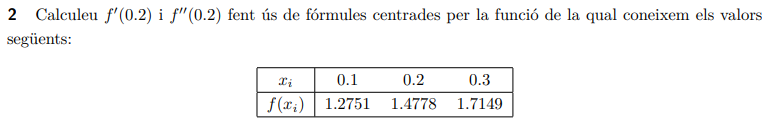

clearvars;
x = [0.1, 0.2,0.3]; y = [1.2751 1.4778 1.7149];
h = x(2)-x(1);
yp = (y(3)-y(1))/(2*h);
ypp = (y(3)-2*y(2)+y(1))/(h^2);
rowNames = {'y´(2)','y´´(2)'};
varNames = {'valor aproximat'};
R = [yp; ypp];
T = array2table(R,"RowNames",rowNames,"VariableNames",varNames); disp(T)

              valor aproximat
              _______________

    y´(2)          2.199     
    y´´(2)          3.44     



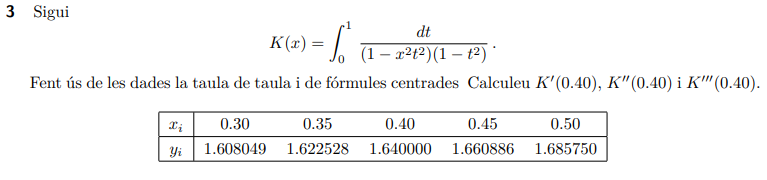

x = [0.3:0.05:0.5];
x2 = x.^2;
y = round(ellipke(x2),7,'significant');     % complete elliptic integral
T = array2table([x;y]',"VariableNames",{'x_i','y_i'}); disp(T)

    x_i      y_i  
    ____    ______

     0.3     1.608
    0.35    1.6225
     0.4      1.64
    0.45    1.6609
     0.5    1.6858



h = x(2) - x(1);  % separació equidistant
yp = (y(4)-y(2))/(2*h);                     % K'(0.40) centrada derivada primera
ypp = (y(4)-2*y(3)+y(2))/(h^2);             % K''(0.40) centrada derivada segona
yppp = (y(5)-2*y(4)+2*y(2)-y(1))/(8*h^3);   % K'''(0.40) centrada derivada tercera
rowNames = {'K´(0.4)','K´´(0.4)','K´´´(0.4)'};
varNames = {'valor aproximat'};
R = [yp;ypp;yppp];
T = array2table(R,"RowNames",rowNames,"VariableNames",varNames); disp(T)

                 valor aproximat
                 _______________

    K´(0.4)          0.38358    
    K´´(0.4)          1.3656    
    K´´´(0.4)          0.985    



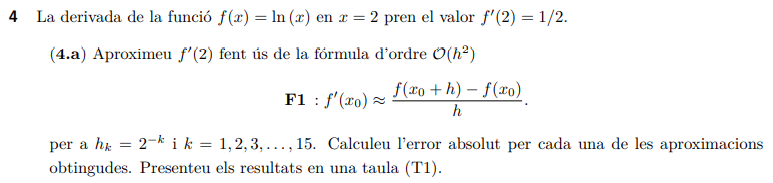

format shortG
% Fórmula endavant
f = @(x) log(x);
k = 0:14;
h = 1./2.^k;
fp = (f(2+h)-f(2))./h;

er = abs(fp-0.5);
taula = [h; fp; er]'

taula =             1      0.40547     0.094535
          0.5      0.44629     0.053713
         0.25      0.47113     0.028868
        0.125        0.485     0.015003
       0.0625      0.49235    0.0076535
      0.03125      0.49613     0.003866
     0.015625      0.49806     0.001943
    0.0078125      0.49903   0.00097403
    0.0039063      0.49951   0.00048765
    0.0019531      0.49976   0.00024398


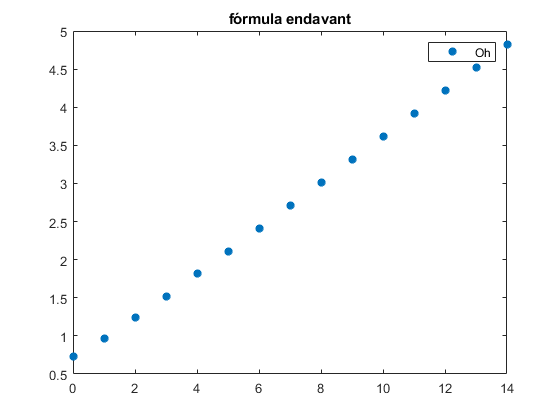

plot(k,-log10(2*er),'*','LineWidth',2),legend('Oh'),title('fórmula endavant')

Repetir l'exercici 4 utilitzant la fórmula $\mathbf{F2}\::f^{\prime}(x_0)\approx\frac{f(x_0+h)-f(x_0-h)}{2h}.$

% Fórmula centrada
f = @(x) log(x);
k = 0:14;
h = 1./2.^k;
fp2 = (f(2+h)-f(2-h))./(2*h);
er2 = abs(fp2-0.5);
taula = [h; fp2; er2]'

taula =             1      0.54931     0.049306
          0.5      0.51083     0.010826
         0.25      0.50263    0.0026289
        0.125      0.50065   0.00065257
       0.0625      0.50016   0.00016286
      0.03125      0.50004   4.0696e-05
     0.015625      0.50001   1.0173e-05
    0.0078125          0.5   2.5432e-06
    0.0039063          0.5   6.3578e-07
    0.0019531          0.5   1.5895e-07


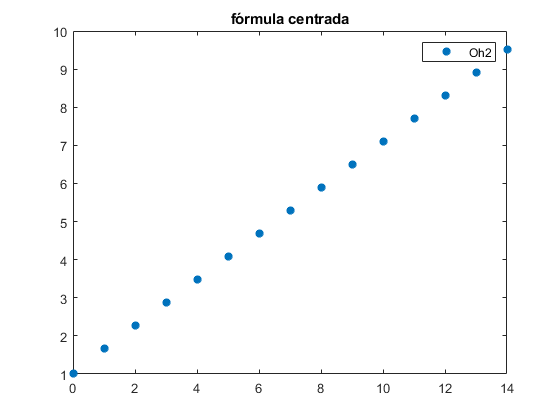

% Gràficament
plot(k,-log10(2*er2),'*','LineWidth',2), legend('Oh2'),title('fórmula centrada')

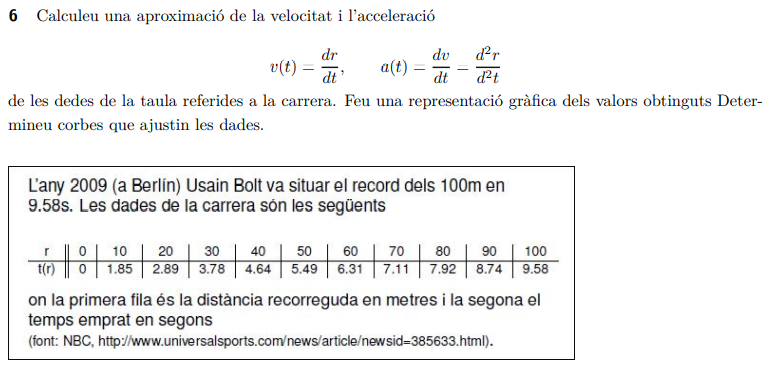

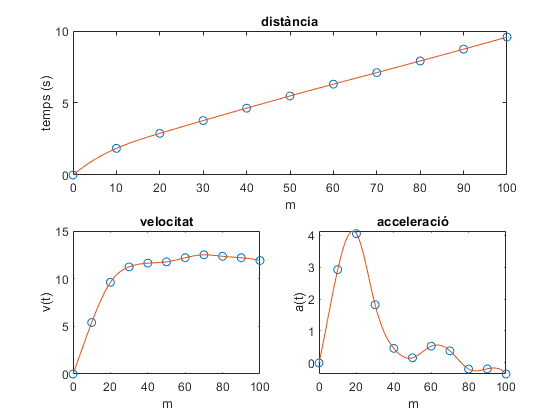

format short g
r = 0:10:100;
t = [0 1.85 2.89 3.78 4.64 5.49 6.31 7.11 7.92 8.74 9.58];
% Velocitat i acceleració
k = length(r);
v(1:k) = 0; a(1:k) = 0;
for i = 2:k
    v(i) = (r(i)-r(i-1))/(t(i)-t(i-1));
    a(i) = (v(i)-v(i-1))/(t(i)-t(i-1));
end
taula = [r;t;v;a]';
% Gràfics
xx = 0:1:100;
rr = spline(r,t,xx);
subplot(2,2,[1,2]),plot(r,t,'o',xx,rr)
xlabel('m'); ylabel('temps (s)');
title('distància')
vv = spline(r,v,xx);
subplot(2,2,3),plot(r,v,'o',xx,vv)
xlabel('m'); ylabel('v(t)');
title('velocitat'),xticks([0,20,40,60,80,100])
aa = spline(r,a,xx);
subplot(2,2,4),plot(r,a,'o',xx,aa);
xlabel('m'); ylabel('a(t)');
title('acceleració'),xticks([0,20,40,60,80,100])